## Loading files

clc
clear

files = dir('C:\Users\laula\Desktop\TrainMatlab/*.csv');
for i=1:length(files)
    readmatrix(strcat(files(i).folder,'\',files(i).name));
end
% Scale cpr-power
Ftrain1(:,11) = Ftrain1(:,11) / 1000;

Unrecognized function or variable 'Ftrain1'.

Ftrain2(:,11) = Ftrain2(:,11) / 1000;
Ftrain3(:,11) = Ftrain3(:,11) / 1000;
Ftrain4(:,11) = Ftrain4(:,11) / 1000;
Ftrain5(:,11) = Ftrain5(:,11) / 1000;
Ftrain6(:,11) = Ftrain6(:,11) / 1000;
Ftrain7(:,11) = Ftrain7(:,11) / 1000;
Ftrain8(:,11) = Ftrain8(:,11) / 1000;
Ftrain9(:,11) = Ftrain9(:,11) / 1000;
Ftrain10(:,11) = Ftrain10(:,11) / 1000;
Ftrain11(:,11) = Ftrain11(:,11) / 1000;
Ftrain12(:,11) = Ftrain12(:,11) / 1000;
Ftrain13(:,11) = Ftrain13(:,11) / 1000;
Ftrain14(:,11) = Ftrain14(:,11) / 1000;
Ftrain15(:,11) = Ftrain15(:,11) / 1000;
Ftrain16(:,11) = Ftrain16(:,11) / 1000;
Ftrain17(:,11) = Ftrain17(:,11) / 1000;
Ftrain18(:,11) = Ftrain18(:,11) / 1000;
Ftrain19(:,11) = Ftrain19(:,11) / 1000;
Ftrain20(:,11) = Ftrain20(:,11) / 1000;
Ntrain1(:,11) = Ntrain1(:,11) / 1000;

% Noise
% sigma = .5;
% 
% Ftrain1 = Ftrain1 + normrnd(0,sigma,108000,14);
% Ftrain2 = Ftrain2 + normrnd(0,sigma,108000,14);
% Ftrain3 = Ftrain3 + normrnd(0,sigma,108000,14);
% Ftrain4 = Ftrain4 + normrnd(0,sigma,108000,14);
% Ftrain5 = Ftrain5 + normrnd(0,sigma,108000,14);
% Ftrain6 = Ftrain6 + normrnd(0,sigma,108000,14);
% Ftrain7 = Ftrain7 + normrnd(0,sigma,108000,14);
% Ftrain8 = Ftrain8 + normrnd(0,sigma,108000,14);
% Ftrain9 = Ftrain9 + normrnd(0,sigma,90000,14);
% Ftrain10 = Ftrain10 + normrnd(0,sigma,108000,14);
% Ftrain11 = Ftrain11 + normrnd(0,sigma,108000,14);
% Ftrain12 = Ftrain12 + normrnd(0,sigma,108000,14);
% Ftrain13 = Ftrain13 + normrnd(0,sigma,108000,14);
% Ftrain14 = Ftrain14 + normrnd(0,sigma,108000,14);
% Ftrain15 = Ftrain15 + normrnd(0,sigma,108000,14);
% Ftrain16 = Ftrain16 + normrnd(0,sigma,108000,14);
% Ftrain17 = Ftrain17 + normrnd(0,sigma,108000,14);
% Ftrain18 = Ftrain18 + normrnd(0,sigma,108000,14);
% Ftrain19 = Ftrain19 + normrnd(0,sigma,108000,14);
% Ftrain20 = Ftrain20 + normrnd(0,sigma,108000,14);
% Ntrain1 = Ntrain1 + normrnd(0,sigma,108000,14);

## Generating data

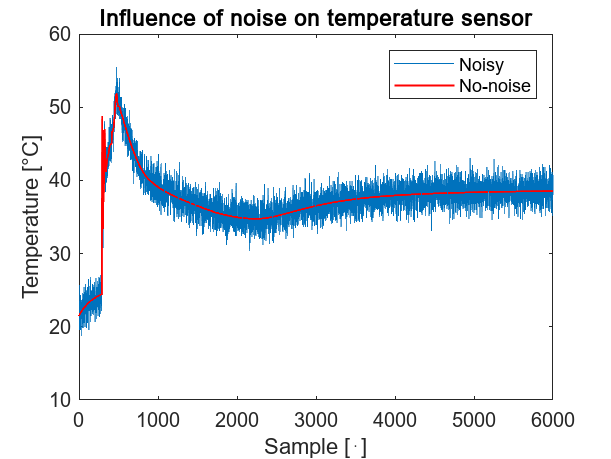

OP_offset = 100;
setpoints = 12;
offset = OP_offset * setpoints;
% OP_offset = 50;
trainingData = zeros(25200,14);
for j=1:setpoints
    n = (j-1)*OP_offset;
    startPoint = 6000*j+5000;
    endPoint = startPoint + OP_offset - 1;
    trainingData(offset*0+n+1:offset*0+j*OP_offset,:) = Ftrain1(startPoint:endPoint,:);
    trainingData(offset*1+n+1:offset*1+j*OP_offset,:) = Ftrain2(startPoint:endPoint,:);
    trainingData(offset*2+n+1:offset*2+j*OP_offset,:) = Ftrain3(startPoint:endPoint,:);
    trainingData(offset*3+n+1:offset*3+j*OP_offset,:) = Ftrain4(startPoint:endPoint,:);
    trainingData(offset*4+n+1:offset*4+j*OP_offset,:) = Ftrain5(startPoint:endPoint,:);
    trainingData(offset*5+n+1:offset*5+j*OP_offset,:) = Ftrain6(startPoint:endPoint,:);
    trainingData(offset*6+n+1:offset*6+j*OP_offset,:) = Ftrain7(startPoint:endPoint,:);
    trainingData(offset*7+n+1:offset*7+j*OP_offset,:) = Ftrain8(startPoint:endPoint,:);
    trainingData(offset*8+n+1:offset*8+j*OP_offset,:) = Ftrain9(startPoint:endPoint,:);
    trainingData(offset*9+n+1:offset*9+j*OP_offset,:) = Ftrain10(startPoint:endPoint,:);
    trainingData(offset*10+n+1:offset*10+j*OP_offset,:) = Ftrain11(startPoint:endPoint,:);
    trainingData(offset*11+n+1:offset*11+j*OP_offset,:) = Ftrain12(startPoint:endPoint,:);
    trainingData(offset*12+n+1:offset*12+j*OP_offset,:) = Ftrain13(startPoint:endPoint,:);
    trainingData(offset*13+n+1:offset*13+j*OP_offset,:) = Ftrain14(startPoint:endPoint,:);
    trainingData(offset*14+n+1:offset*14+j*OP_offset,:) = Ftrain15(startPoint:endPoint,:);
    trainingData(offset*15+n+1:offset*15+j*OP_offset,:) = Ftrain16(startPoint:endPoint,:);
    trainingData(offset*16+n+1:offset*16+j*OP_offset,:) = Ftrain17(startPoint:endPoint,:);
    trainingData(offset*17+n+1:offset*17+j*OP_offset,:) = Ftrain18(startPoint:endPoint,:);
    trainingData(offset*18+n+1:offset*18+j*OP_offset,:) = Ftrain19(startPoint:endPoint,:);
    trainingData(offset*19+n+1:offset*19+j*OP_offset,:) = Ftrain20(startPoint:endPoint,:);
    trainingData(offset*20+n+1:offset*20+j*OP_offset,:) = Ntrain1(startPoint:endPoint,:);
end
% WIP
N = offset;
trainingLabel = zeros(1,N*21);
Nk = zeros(1,21);
for i=1:21
    trainingLabel(1,(i-1)*N+1:i*N) = i*ones(1,N);
    Nk(i) = N;
end

% Noise to Tdis, Tret, Tsuc, Tsup
trainingData(:,5) = trainingData(:,5) + normrnd(0,sqrt(2),25200,1);
trainingData(:,6) = trainingData(:,6) + normrnd(0,sqrt(2),25200,1);
trainingData(:,7) = trainingData(:,7) + normrnd(0,sqrt(2),25200,1);
trainingData(:,9) = trainingData(:,9) + normrnd(0,sqrt(2),25200,1);
% Psuc, CprPower, Density
trainingData(:,12) = [];
trainingData(:,11) = [];
trainingData(:,2) = [];


% Do-not uncomment these
% save('trainingDataReduced.mat',"trainingData", "trainingLabel")
% save('trainingData.mat',"Ftrain1","Ftrain2","Ftrain3","Ftrain4","Ftrain5","Ftrain6","Ftrain7","Ftrain8","Ftrain9","Ftrain10","Ftrain11","Ftrain12","Ftrain13","Ftrain14","Ftrain15","Ftrain16","Ftrain17","Ftrain18","Ftrain19","Ftrain20","Ntrain1","trainingData", "trainingLabel")

## plotting

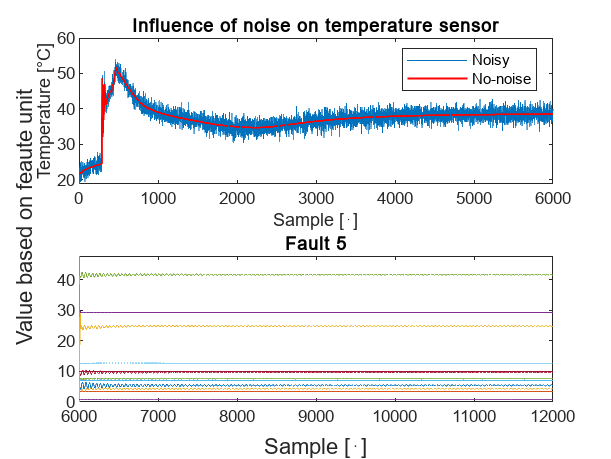

x = linspace(1,6000,6000);
plot(x,Ntrain1(30001:36000,5) + normrnd(0,sqrt(2),6000,1))
hold on
plot(x,Ntrain1(30001:36000,5),Color=[1,0,0],LineWidth=1)
hold off
title("Influence of noise on temperature sensor")
ylabel("Temperature [°C]")
xlabel("Sample [⋅]")
legend("Noisy","No-noise")
saveas(gcf,'Images/NoisyData','epsc')


x = linspace(6001,12000,6000);
fig = figure;
subplot(2,1,1)
plot(Ntrain1(1:6000,:),LineWidth=1)
title("Non-faulty")
ylim([-10 90])
subplot(2,1,2)
plot(x,Ftrain5(6001:12000,:),LineWidth=1)'

ans =   1×14 Line array:

    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line


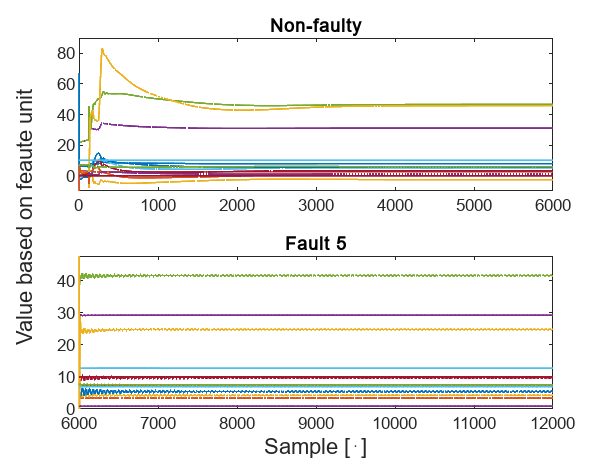

title("Fault 5")
handle = axes(fig,'visible','off');
handle.XLabel.Visible='on';
handle.YLabel.Visible='on';
xlabel(handle,"Sample [⋅]")
ylabel(handle,"Value based on feaute unit")
saveas(gcf,'Images/dataSample','epsc')

## Load validation data

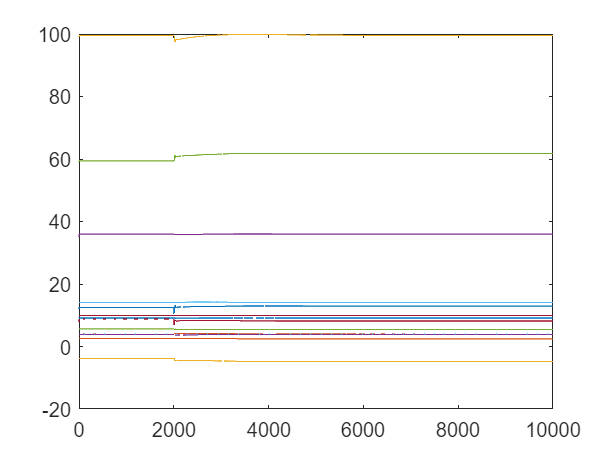

clc
clear
files = dir('./newValid/*.csv');
for i=1:length(files)
    load(strcat(files(i).folder,'\',files(i).name));
end
NewValid_f1(:,11) = NewValid_f1(:,11) / 1000;
NewValid_f2(:,11) = NewValid_f2(:,11) / 1000;
NewValid_f3(:,11) = NewValid_f3(:,11) / 1000;
NewValid_f4(:,11) = NewValid_f4(:,11) / 1000;
NewValid_f5(:,11) = NewValid_f5(:,11) / 1000;
NewValid_f6(:,11) = NewValid_f6(:,11) / 1000;
NewValid_f7(:,11) = NewValid_f7(:,11) / 1000;
NewValid_f8(:,11) = NewValid_f8(:,11) / 1000;
NewValid_f9(:,11) = NewValid_f9(:,11) / 1000;
NewValid_f10(:,11) = NewValid_f10(:,11) / 1000;
NewValid_f11(:,11) = NewValid_f11(:,11) / 1000;
NewValid_f12(:,11) = NewValid_f12(:,11) / 1000;
NewValid_f13(:,11) = NewValid_f13(:,11) / 1000;
NewValid_f14(:,11) = NewValid_f14(:,11) / 1000;
NewValid_f15(:,11) = NewValid_f15(:,11) / 1000;
NewValid_f16(:,11) = NewValid_f16(:,11) / 1000;
NewValid_f17(:,11) = NewValid_f17(:,11) / 1000;
NewValid_f18(:,11) = NewValid_f18(:,11) / 1000;
NewValid_f19(:,11) = NewValid_f19(:,11) / 1000;
NewValid_f20(:,11) = NewValid_f20(:,11) / 1000;
NewValid_n1(:,11) = NewValid_n1(:,11) / 1000;

plot(NewValid_f1)

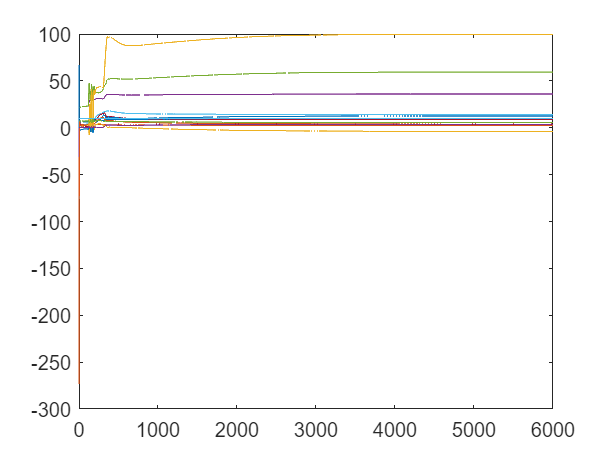

plot(NewValid_n1)


ValidationData = [NewValid_f1(5001:end,:); NewValid_f2(5001:end,:); NewValid_f3(5001:end,:); NewValid_f4(5001:end,:); NewValid_f5(5001:end,:); NewValid_f6(5001:end,:); NewValid_f7(5001:end,:); NewValid_f8(5001:end,:); NewValid_f9(5001:end,:); NewValid_f10(5001:end,:); NewValid_f11(5001:end,:); NewValid_f12(5001:end,:); NewValid_f13(5001:end,:); NewValid_f14(5001:end,:); NewValid_f15(5001:end,:); NewValid_f16(5001:end,:); NewValid_f17(5001:end,:); NewValid_f18(5001:end,:); NewValid_f19(5001:end,:); NewValid_f20(5001:end,:); NewValid_n1(3001:end,:)]

ValidationData =     9.1109    2.4552   -4.7639   35.9698   61.7551   14.0777    8.1704   12.9343    3.9892   99.6646    3.8107    5.4591    4.0000   10.0000
    9.1109    2.4552   -4.7638   35.9698   61.7550   14.0777    8.1704   12.9343    3.9892   99.6645    3.8107    5.4591    4.0000   10.0000
    9.1109    2.4552   -4.7638   35.9698   61.7550   14.0777    8.1704   12.9343    3.9892   99.6644    3.8107    5.4591    4.0000   10.0000
    9.1109    2.4552   -4.7638   35.9698   61.7549   14.0777    8.1704   12.9342    3.9892   99.6643    3.8107    5.4591    4.0000   10.0000
    9.1109    2.4552   -4.7638   35.9698   61.7549   14.0777    8.1704   12.9342    3.9892   99.6642    3.8106    5.4591    4.0000   10.0000
    9.1109    2.4552   -4.7638   35.9698   61.7548   14.0777    8.1704   12.9342    3.9892   99.6641    3.8106    5.4591    4.0000   10.0000
    9.1109    2.4552   -4.7637   35.9698   61.7548   14.0777    8.1704   12.9342    3.9892   99.6639    3.8106    5.4591    4.0000   10.0


N=5000;
for i=1:20
    ValLabel(1,(i-1)*N+1:i*N) = i*ones(1,N);
end
ValLabel(1,20*5000+1:20*5000+3000) = 21*ones(1,3000);

ValidationData(:,12) = [];
ValidationData(:,11) = [];
ValidationData(:,2) = [];

save('ValidationData.mat',"ValidationData","ValLabel","NewValid_f1","NewValid_f2","NewValid_f3","NewValid_f4","NewValid_f5","NewValid_f6","NewValid_f7","NewValid_f8","NewValid_f9","NewValid_f10","NewValid_f11","NewValid_f12","NewValid_f13","NewValid_f14","NewValid_f15","NewValid_f16","NewValid_f17","NewValid_f18","NewValid_f19","NewValid_f20","NewValid_n1")